# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 정우린**

**학번**** : 201910988**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/JeongWooRin/DSP_hw2**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

%DFT 결과
x = [1,2,2,1]; N=4; X = dft(x,N);  
magX = abs(X), phaX = angle(X)*180/pi

magX =     6.0000    1.4142    0.0000    1.4142


phaX =          0 -135.0000  -90.0000  135.0000


%IDFT 결과
x = [1,2,2,1]; N=4; X = idft(x,N);  
magX = abs(X), phaX = angle(X)*180/pi

magX =     1.5000    0.3536    0.0000    0.3536


phaX =          0  135.0000   90.0000 -135.0000


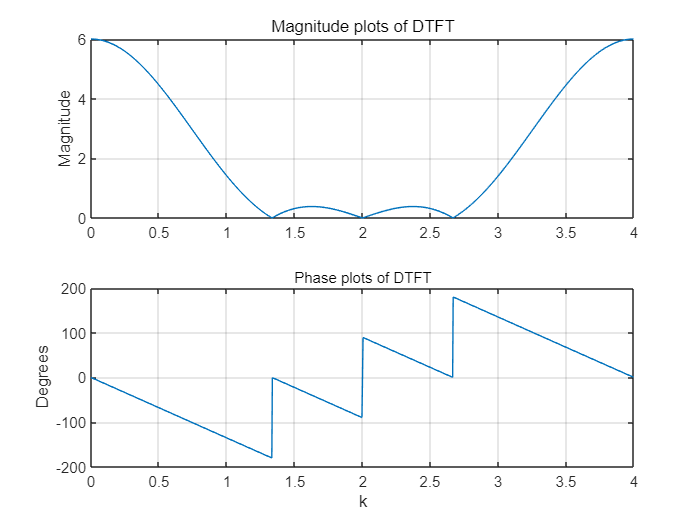

% DFT 결과와 DTFT 결과 비교
% 다음은 코드로 'DTFT 결과 그래프'를 그렸다.
n = 0:3; xn = [1,2,2,1]; N = length(xn);
Xk = dft(xn,N); k = 0:N-1;

[X,w] = freqz(xn,1,1000,'whole'); 
magX = abs(X); phaX = angle(X)*180/pi; 
Dw = (2*pi)/N; 
subplot(2,1,1); plot(w/Dw,magX); grid
ylabel('Magnitude');
title('Magnitude plots of DTFT','fontsize',10);
hold off
subplot(2,1,2); plot(w/Dw,phaX); grid
xlabel('k'); ylabel('Degrees');
title('Phase plots of DTFT','fontsize',9);
hold off

% DTFT 값은 아래 그래프의 결과로 확인가능하다.
% DFT는 DTFT에서 얻은 주파수 축 신호를 N개로 discrete 하게 쪼개는 것이다.
% N=4이고 이에 따라 나눴으니 DFT값은 magX = abs(X), phaX = angle(X)*180/pi을 진행하여 나온 결과(magX, phaX)처럼 나오는 것이다.

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

 %DFT 결과
x = [1,2,2,1, zeros(1,4)]; N=8; X = dft(x,N); 
magX = abs(X), phaX = angle(X)*180/pi

magX =     6.0000    4.4609    1.4142    0.3170    0.0000    0.3170    1.4142    4.4609


phaX =          0  -67.5000 -135.0000  -22.5000  -90.0000   22.5000  135.0000   67.5000


 %IDFT 결과
x = [1,2,2,1, zeros(1,4)]; N=8; X = idft(x,N); 
magX = abs(X), phaX = angle(X)*180/pi

magX =     0.7500    0.5576    0.1768    0.0396    0.0000    0.0396    0.1768    0.5576


phaX =          0   67.5000  135.0000   22.5000   90.0000  -22.5000 -135.0000  -67.5000


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

Xtilde1 = [4,1,-1,1]; N = 4; xtiled1 = dfs(Xtilde1,N)

xtiled1 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

xtilde3 = [1,0,-1,-1,0]; N = 5; Xtilde3 = dfs(xtilde3,N)

Xtilde3 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

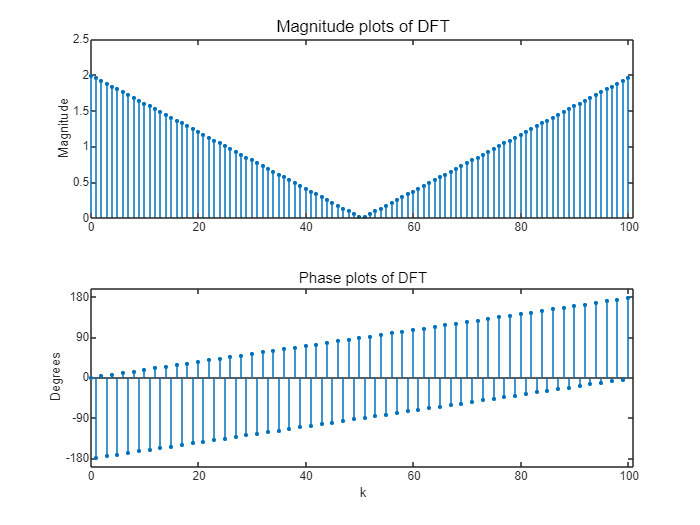


n = 0:100; xn = sinc((n-50)/2).^2; N = length(xn);
Xk = dft(xn,N); k = 0:N-1;

mag_Xk = abs(Xk); pha_Xk = angle(Xk)*180/pi;
zei = find(mag_Xk < 0.00001);

pha_Xk(zei) = zeros(1,length(zei));

Hf = figure();
set(Hf,'NumberTitle','off'); 

subplot(2,1,1); Hs1 = stem(k,mag_Xk,'filled'); 
set(Hs1,'markersize',2); 

set(gca,'XTick',[0:20:N],'fontsize',7);  %gca는 좌표축의 글꼴 큭, 눈금방향, 눈금 길이 및 축 제한 설정함.
axis([0,N,0,2.5])                         %gca사용해 현재 좌표축 참조함.

set(gca,'YTick',[0:0.5:2.5],'fontsize',7);
ylabel('Magnitude');
title('Magnitude plots of DFT','fontsize',10); hold on

subplot(2,1,2); Hs2 = stem(k,pha_Xk,'filled'); %그래프 2 그린거
set(Hs2,'markersize',2); %

set(gca,'XTick',[0:20:N],'fontsize',7);
axis([0,N,-200,200])

set(gca,'YTick',[-180;-90;0;90;180],'fontsize',7);
xlabel('k'); ylabel('Degrees');
title('Phase plots of DFT','fontsize',9); 

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

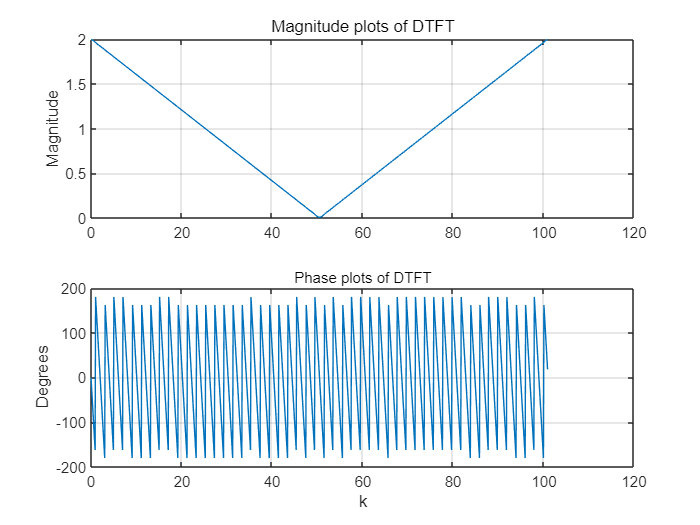

n = 0:100; xn = sinc((n-50)/2).^2; N = length(xn);
Xk = dft(xn,N); k = 0:N-1;

mag_Xk = abs(Xk); pha_Xk = angle(Xk)*180/pi;
zei = find(mag_Xk < 0.00001);

pha_Xk(zei) = zeros(1,length(zei));

Hf = figure();
set(Hf,'NumberTitle','off'); 

subplot(2,1,1); Hs1 = stem(k,mag_Xk,'filled'); 
set(Hs1,'markersize',2); 

set(gca,'XTick',[0:20:N],'fontsize',7);  
axis([0,N,0,2.5])                        

set(gca,'YTick',[0:0.5:2.5],'fontsize',7);
ylabel('Magnitude');
title('Magnitude plots of DFT','fontsize',10); hold off

subplot(2,1,2); Hs2 = stem(k,pha_Xk,'filled'); 
set(Hs2,'markersize',2); %

set(gca,'XTick',[0:20:N],'fontsize',7);
axis([0,N,-200,200])

set(gca,'YTick',[-180;-90;0;90;180],'fontsize',7);
xlabel('k'); ylabel('Degrees');
title('Phase plots of DFT','fontsize',9);  hold off  % 3-1)의 값을 활용한다.

[X,w] = freqz(xn,1,1000,'whole'); 
mag_X = abs(X); pha_X = angle(X)*180/pi; 
Dw = (2*pi)/N; 
subplot(2,1,1); plot(w/Dw,mag_X); grid
ylabel('Magnitude');
title('Magnitude plots of DTFT','fontsize',10);
hold off
subplot(2,1,2); plot(w/Dw,pha_X); grid
xlabel('k'); ylabel('Degrees');
title('Phase plots of DTFT','fontsize',9);
hold off

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

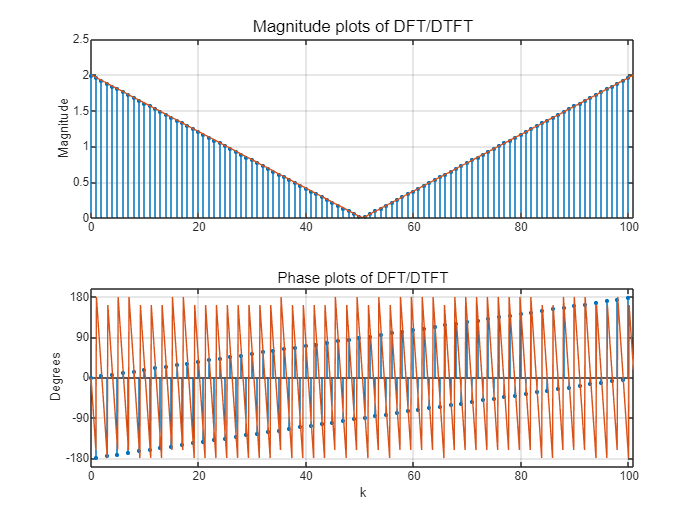

Hf = figure();
set(Hf,'NumberTitle','off'); 
subplot(2,1,1); Hs1 = stem(k,mag_Xk,'filled'); 
set(Hs1,'markersize',2); 
set(gca,'XTick',[0:20:N],'fontsize',7);  
axis([0,N,0,2.5])                        
set(gca,'YTick',[0:0.5:2.5],'fontsize',7);
hold on

subplot(2,1,2); Hs2 = stem(k,pha_Xk,'filled'); 
set(Hs2,'markersize',2); %
set(gca,'XTick',[0:20:N],'fontsize',7);
axis([0,N,-200,200])
set(gca,'YTick',[-180;-90;0;90;180],'fontsize',7);
hold on

[X,w] = freqz(xn,1,1000,'whole'); 
mag_X = abs(X); pha_X = angle(X)*180/pi; 
Dw = (2*pi)/N;
subplot(2,1,1); plot(w/Dw,mag_X); grid 
ylabel('Magnitude');
title('Magnitude plots of DFT/DTFT','fontsize',10);

subplot(2,1,2); plot(w/Dw,pha_X); grid
xlabel('k'); ylabel('Degrees');
title('Phase plots of DFT/DTFT','fontsize',9); 
hold off

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

- DFT X(k)로부터 DTFT X(e^jw)를 재구성할 수 있습니다.

- 가능한 경우는 DFT의 길이가 신호x(n)의 길이보다 크거나 같다면 가능합니다.

- 재구성에 필요한 보간 공식은 다음과 같습니다. (일반화된 보간공식)

- 위의 DFT X(k)를  DTFT X(e^jw)로 재구성하는데 필요한 공식은 다음과 같습니다.

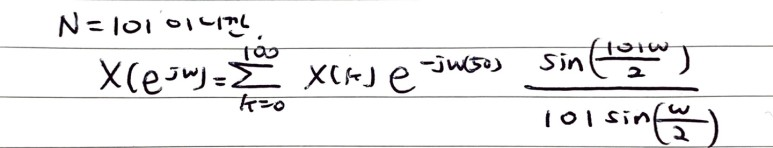

function [xn] = idft(Xk,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end

function [Xk] = dfs(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

function [Xk] = dft(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end